 
clearvars;
clear all;
clc;
close all; % Close any existing figures
rng(0); % for reproducibility

% --- Problem Data: Create the image with a missing square ---
image_size = 50; % The image will be 50x50 pixels
hole_size = 20;  % The missing square will be 20x20 pixels

% 1. Create the ground truth image (all white)
M_true = ones(image_size, image_size);

% 2. Create the Omega mask (1 = observed, 0 = missing)
Omega = ones(image_size, image_size);
start_idx = floor((image_size - hole_size) / 2) + 1;
end_idx = start_idx + hole_size - 1;
Omega(start_idx:end_idx, start_idx:end_idx) = 0;

% 3. Create the input matrix M with the missing region
M = M_true .* Omega;

% --- Parameters ---
r = 1;              % IMPORTANT: The true rank of a solid color image is 1
tol = 1e-8;         % convergence tolerance
maxiter = 1000;     % maximum iterations
rho = 1.0;          % penalty parameter
gamma = 1.0;        % dual step size

% sizes
[m, n] = size(M);

% --- Initialization ---
Y = rand(r, n);
Z = M .* Omega;
Lambda = zeros(m, n);

% Initial X calculation
Yt = Y';
A = Y * Yt;
A_inv = pinv(A); % Use pseudoinverse for stability
X = (Z * Yt) * A_inv;

% For monitoring
err_hist = zeros(maxiter, 1);

% --- ADMM Loop (Your code is unchanged here) ---
converged = false;
for iter = 1:maxiter
    % Step 1: Update X
    Yt = Y';
    A = Y * Yt;
    A_inv = pinv(A);
    X = (Z * Yt) * A_inv;

    % Step 2: Update Y
    Xt = X';
    B = Xt * X;
    B_inv = pinv(B);
    Y = B_inv * (Xt * Z);

    % Step 3: Update Z
    XY = X * Y;
    Z_Omega = (1 / (1 + rho)) * ( (XY - Lambda) .* Omega + rho * M .* Omega );
    Z_Omega_c = XY .* (~Omega);
    Z = Z_Omega + Z_Omega_c;

    % Step 4: Update Lambda
    Delta = (Z - M) .* Omega;
    Lambda(Omega==1) = Lambda(Omega==1) + gamma * rho * Delta(Omega==1);

    % Convergence check
    numer = norm( (Z - XY) .* Omega, 'fro' );
    denom = max(1, norm(M .* Omega, 'fro'));
    rel_error = numer / denom;
    err_hist(iter) = rel_error;

    if rel_error < tol
        converged = true;
        break;
    end
end

% Final reconstructed matrix
Z_completed = X * Y;

% --- Output and Visualization ---
fprintf('Converged: %d, Iterations: %d\n', converged, iter);

Converged: 1, Iterations: 49


fprintf('Final Relative Error (observed): %.2e\n', rel_error);

Final Relative Error (observed): 6.54e-09


fprintf('Rank of completed matrix: %d\n', rank(Z_completed));

Rank of completed matrix: 1


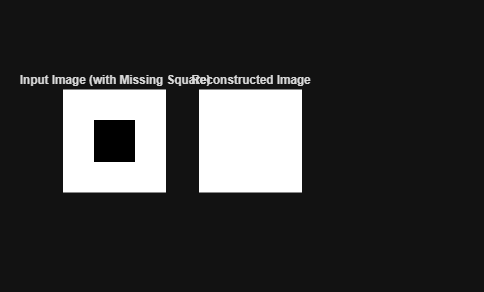


figure;
colormap('gray'); % Use a grayscale colormap

% 1. Show the input image with the black square
subplot(1, 3, 1);
imshow(M);
title('Input Image (with Missing Square)');

% 2. Show the reconstructed image
subplot(1, 3, 2);
imshow(Z_completed);
title('Reconstructed Image');